# Global params

% zaklinadla
clear vars; clc; close all;

addpath('funcs'); 

data_path = 'data';
file_list_folder = 'filelists';
K = 16;

% fileLists = {'FileList2206.txt', 
%              'FileList2203.txt',
%              'FileList2207.txt',
%              'FileList2204.txt',
%              'FileListAll.txt'}; % List of datasets

fileLists = {'FileList2501.txt' 'FileList2101.txt' 'FileList2105.txt'};
aggregatedFeatures = struct();

## Extract, store and plot features

for i = 1:length(fileLists)
    % Construct full path to the file list
    fileListPath = fullfile(file_list_folder, fileLists{i});
    disp(['Processing file list: ', fileListPath]);
    
    if exist(fileListPath, 'file')
        % Open and read the file list
        fileID = fopen(fileListPath, 'r');
        fileNames = textscan(fileID, '%s'); % Read all lines as strings
        fclose(fileID);
        % Convert to a cell array of strings
        fileNames = fileNames{1};
        
        % Process each file in the list
        for j = 1:length(fileNames)
            % Construct full path to the audio file
            audioFilePath = fullfile(fileNames{j});
            
            % Check if the audio file exists
            if exist(audioFilePath, 'file')
                disp(['Processing: ', audioFilePath]);
                
                % Call xtractWord function to extract features
                [detectedWord, wordStart, wordEnd, logEnergy, zcr] = xtractWord(audioFilePath);
                
                if ~isempty(detectedWord)
                    % Frame extraction
                    frames = buffer(detectedWord, 400, 240, 'nodelay'); 
                    % Compute spectral features using K = 16 spectral bands
                    spectralFeatures = kSpectralFeatures(frames, K);
                    
                    % Aggregate features into our global structure
                    aggregatedFeatures = aggregateFeatures(aggregatedFeatures, audioFilePath, wordStart, wordEnd, logEnergy, zcr, spectralFeatures);
                    
                 
                    % plotWordDetection(audioFilePath, wordStart, wordEnd, logEnergy, zcr, spectralFeatures);
                else
                    disp('No word detected, skipping spectral feature extraction.');
                end
                
            else
                disp(['File not found: ', audioFilePath]);
            end
        end
    else
        disp(['File list not found: ', fileListPath]);
    end
end

%% Save aggregated features for each user into one MAT file per user
userIDs = fieldnames(aggregatedFeatures);
for i = 1:length(userIDs)
    pID = userIDs{i};
    features = aggregatedFeatures.(pID);
    
    % Ensure the output directory exists
    if ~exist(data_path, 'dir')
        mkdir(data_path);
    end
    
    outputFile = fullfile(data_path, [pID, '_features.mat']);
    save(outputFile, 'features');
    disp(['Aggregated features saved to: ', outputFile]);
end




## Compute DTW and LTW for each feature

clear; clc; % zaklinadla

data_path = 'data';
% Get all .mat files for users; files are assumed to be named like "pXXXX_features.mat"
matFiles = dir(fullfile(data_path, 'p*_features.mat'));

% Overall counters for each experiment
overallCorrect_energy = 0;
overallCorrect_energyZCR = 0;
overallCorrect_spectral = 0;
overallCorrect_all = 0;
overallTestSamples = 0;
overallCorrect_zcr = 0;

% Loop over each MAT file (each user)
for k = 1:length(matFiles)
    % Extract user ID from file name (e.g., 'p2501' from 'p2501_features.mat')
    fileName = matFiles(k).name;
    tokens = regexp(fileName, '(p\d+)_features\.mat', 'tokens');
    if isempty(tokens)
        fprintf('Filename %s does not match pattern. Skipping.\n', fileName);
        continue;
    end
    pID = tokens{1}{1};
    fprintf('Processing user: %s\n', pID);
    
    % Load aggregated feature data for this user
    userMAT = fullfile(data_path, fileName);
    userData = load(userMAT);
    features = userData.features;  % "features" is assumed to be a structure array
    
    % Partition into training and testing:
    % Training data are those with sID equal to '01'
    trainIdx = find(arrayfun(@(x) strcmp(x.sID, '01'), features));
    testIdx = setdiff(1:length(features), trainIdx);
    
    trainingFeatures = features(trainIdx);
    testingFeatures  = features(testIdx);
    
    if isempty(trainingFeatures)
        fprintf('No training data (sID=01) for user %s. Skipping recognition for this user.\n', pID);
        continue;
    end
    
    numTest = length(testingFeatures);
    numTrain = length(trainingFeatures);
    overallTestSamples = overallTestSamples + numTest;
    
    %% Experiment 1: Energy Only
    dtwDistances_energy = zeros(numTest, numTrain);
    for i = 1:numTest
        testFeat = testingFeatures(i).logEnergy(:);
        for j = 1:numTrain
            trainFeat = trainingFeatures(j).logEnergy(:);
            [dtwDist, ~, ~] = ComputeDTW(testFeat, trainFeat, 1);
            dtwDistances_energy(i,j) = dtwDist;
        end
    end
    [~, bestMatchIdx_energy] = min(dtwDistances_energy, [], 2);
    correct_energy = 0;
    for i = 1:numTest
        if trainingFeatures(bestMatchIdx_energy(i)).c == testingFeatures(i).c
            correct_energy = correct_energy + 1;
        end
    end
    accuracy_energy = (correct_energy / numTest) * 100;
    fprintf('User %s - Accuracy (Energy Only): %.2f%% (%d/%d correct)\n', pID, accuracy_energy, correct_energy, numTest);
    overallCorrect_energy = overallCorrect_energy + correct_energy;
    
    %% Experiment 1.5: ZCR Only
    dtwDistances_zcr = zeros(numTest, numTrain);
    for i = 1:numTest
        testFeat = testingFeatures(i).zcr(:);
        for j = 1:numTrain
            trainFeat = trainingFeatures(j).zcr(:);
            [dtwDist, ~, ~] = ComputeDTW(testFeat, trainFeat, 1);
            dtwDistances_zcr(i,j) = dtwDist;
        end
    end
    [~, bestMatchIdx_zcr] = min(dtwDistances_zcr, [], 2);
    correct_zcr = 0;
    for i = 1:numTest
        if trainingFeatures(bestMatchIdx_zcr(i)).c == testingFeatures(i).c
            correct_zcr = correct_zcr + 1;
        end
    end
    accuracy_zcr = (correct_zcr / numTest) * 100;
    fprintf('User %s - Accuracy (ZCR Only):    %.2f%% (%d/%d correct)\n', pID, accuracy_zcr, correct_zcr, numTest);
    overallCorrect_zcr = overallCorrect_zcr + correct_zcr;
    
    %% Experiment 2: Energy + ZCR
    dtwDistances_energyZCR = zeros(numTest, numTrain);
    for i = 1:numTest
        testFeat = [testingFeatures(i).logEnergy(:), testingFeatures(i).zcr(:)];
        for j = 1:numTrain
            trainFeat = [trainingFeatures(j).logEnergy(:), trainingFeatures(j).zcr(:)];
            [dtwDist, ~, ~] = ComputeDTW(testFeat, trainFeat, [1, 1]);
            dtwDistances_energyZCR(i,j) = dtwDist;
        end
    end
    [~, bestMatchIdx_energyZCR] = min(dtwDistances_energyZCR, [], 2);
    correct_energyZCR = 0;
    for i = 1:numTest
        if trainingFeatures(bestMatchIdx_energyZCR(i)).c == testingFeatures(i).c
            correct_energyZCR = correct_energyZCR + 1;
        end
    end
    accuracy_energyZCR = (correct_energyZCR / numTest) * 100;
    fprintf('User %s - Accuracy (Energy+ZCR):    %.2f%% (%d/%d correct)\n', pID, accuracy_energyZCR, correct_energyZCR, numTest);
    overallCorrect_energyZCR = overallCorrect_energyZCR + correct_energyZCR;
    
    %% Experiment 3: K-Spectral Features Only
    dtwDistances_spectral = zeros(numTest, numTrain);
    numSpectral = size(trainingFeatures(1).spectralFeatures, 2);
    weights_spectral = ones(1, numSpectral); % equal weights
    for i = 1:numTest
        testFeat = testingFeatures(i).spectralFeatures;
        for j = 1:numTrain
            trainFeat = trainingFeatures(j).spectralFeatures;
            [dtwDist, ~, ~] = ComputeDTW(testFeat, trainFeat, weights_spectral);
            dtwDistances_spectral(i,j) = dtwDist;
        end
    end
    [~, bestMatchIdx_spectral] = min(dtwDistances_spectral, [], 2);
    correct_spectral = 0;
    for i = 1:numTest
        if trainingFeatures(bestMatchIdx_spectral(i)).c == testingFeatures(i).c
            correct_spectral = correct_spectral + 1;
        end
    end
    accuracy_spectral = (correct_spectral / numTest) * 100;
    fprintf('User %s - Accuracy (Spectral):      %.2f%% (%d/%d correct)\n', pID, accuracy_spectral, correct_spectral, numTest);
    overallCorrect_spectral = overallCorrect_spectral + correct_spectral;
    
    %% Experiment 4: All Features Combined (Fixed Weights)
    dtwDistances_all = zeros(numTest, numTrain);
    for i = 1:numTest
        % Extract features for the test sample
        testEnergy = testingFeatures(i).logEnergy(:);
        testZCR = testingFeatures(i).zcr(:);
        testSpectral = testingFeatures(i).spectralFeatures;
        nFrames_test = min([length(testEnergy), length(testZCR), size(testSpectral,1)]);
        testEnergy = testEnergy(1:nFrames_test);
        testZCR = testZCR(1:nFrames_test);
        testSpectral = testSpectral(1:nFrames_test, :);
        testFeat = [testEnergy, testZCR, testSpectral];
        
        for j = 1:numTrain
            % Extract features for the training sample
            trainEnergy = trainingFeatures(j).logEnergy(:);
            trainZCR = trainingFeatures(j).zcr(:);
            trainSpectral = trainingFeatures(j).spectralFeatures;
            nFrames_train = min([length(trainEnergy), length(trainZCR), size(trainSpectral,1)]);
            trainEnergy = trainEnergy(1:nFrames_train);
            trainZCR = trainZCR(1:nFrames_train);
            trainSpectral = trainSpectral(1:nFrames_train, :);
            trainFeat = [trainEnergy, trainZCR, trainSpectral];
            
            % Weight vector: energy: 0.3, ZCR: 0.1, spectral: total 0.6 (distributed equally)
            weights_all = [0.4, 0.1, repmat(0.5/numSpectral, 1, numSpectral)];
            [dtwDist, ~, ~] = ComputeDTW(testFeat, trainFeat, weights_all);
            dtwDistances_all(i,j) = dtwDist;
        end
    end
    [~, bestMatchIdx_all] = min(dtwDistances_all, [], 2);
    correct_all = 0;
    for i = 1:numTest
        if trainingFeatures(bestMatchIdx_all(i)).c == testingFeatures(i).c
            correct_all = correct_all + 1;
        end
    end
    accuracy_all = (correct_all / numTest) * 100;
    fprintf('User %s - Accuracy (All Combined):  %.2f%% (%d/%d correct)\n', pID, accuracy_all, correct_all, numTest);
    overallCorrect_all = overallCorrect_all + correct_all;
    
end

Processing user: p2101


User p2101 - Accuracy (Energy Only): 87.50% (35/40 correct)


User p2101 - Accuracy (ZCR Only):    90.00% (36/40 correct)


User p2101 - Accuracy (Energy+ZCR):    87.50% (35/40 correct)


User p2101 - Accuracy (Spectral):      47.50% (19/40 correct)


User p2101 - Accuracy (All Combined):  52.50% (21/40 correct)


Processing user: p2105


User p2105 - Accuracy (Energy Only): 70.00% (28/40 correct)


User p2105 - Accuracy (ZCR Only):    47.50% (19/40 correct)


User p2105 - Accuracy (Energy+ZCR):    75.00% (30/40 correct)


User p2105 - Accuracy (Spectral):      57.50% (23/40 correct)


User p2105 - Accuracy (All Combined):  57.50% (23/40 correct)


Processing user: p2501


User p2501 - Accuracy (Energy Only): 90.00% (36/40 correct)


User p2501 - Accuracy (ZCR Only):    85.00% (34/40 correct)


User p2501 - Accuracy (Energy+ZCR):    92.50% (37/40 correct)


User p2501 - Accuracy (Spectral):      65.00% (26/40 correct)


User p2501 - Accuracy (All Combined):  55.00% (22/40 correct)



%% Overall accuracy across all users
fprintf('\nOverall Accuracy Across All Users:\n');


Overall Accuracy Across All Users:


fprintf('   Energy Only:           %.2f%% (%d/%d correct)\n', (overallCorrect_energy / overallTestSamples)*100, overallCorrect_energy, overallTestSamples);

   Energy Only:           82.50% (99/120 correct)


fprintf('   ZCR Only:              %.2f%% (%d/%d correct)\n', (overallCorrect_zcr / overallTestSamples)*100, overallCorrect_zcr, overallTestSamples);

   ZCR Only:              74.17% (89/120 correct)


fprintf('   Energy + ZCR:          %.2f%% (%d/%d correct)\n', (overallCorrect_energyZCR / overallTestSamples)*100, overallCorrect_energyZCR, overallTestSamples);

   Energy + ZCR:          85.00% (102/120 correct)


fprintf('   Spectral Only:         %.2f%% (%d/%d correct)\n', (overallCorrect_spectral / overallTestSamples)*100, overallCorrect_spectral, overallTestSamples);

   Spectral Only:         56.67% (68/120 correct)


fprintf('   All Combined:          %.2f%% (%d/%d correct)\n', (overallCorrect_all / overallTestSamples)*100, overallCorrect_all, overallTestSamples);

   All Combined:          55.00% (66/120 correct)


## DEBUG

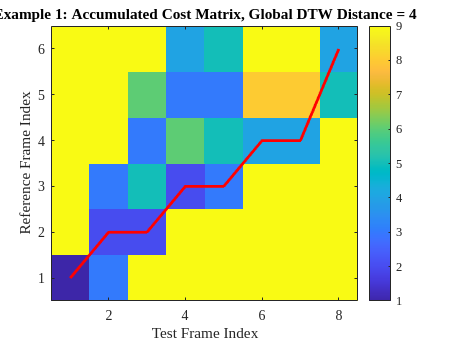

clear; clc; close all;

%% Example 1
% Test and reference sequences
testSeq1 = [1; 4; 5; 2; 3; 7; 6; 1];  % 8 frames
refSeq1  = [2; 5; 2; 6; 2; 1];         % 6 frames

% Compute DTW
[globalDistance1, A1, B1] = ComputeDTW(testSeq1, refSeq1, 1);
% Remove the offset columns from A
A_display1 = A1(:, 3:end);  % Now size is [I x J]
% Transpose for correct orientation: x-axis = test, y-axis = reference
A_plot1 = A_display1';

figure;
imagesc(A_plot1);
colorbar;
title(['Example 1: Accumulated Cost Matrix, Global DTW Distance = ' num2str(globalDistance1)]);
xlabel('Test Frame Index');
ylabel('Reference Frame Index');
axis xy;

% Backtracking for Example 1
I1 = length(testSeq1);
J1 = length(refSeq1);
i = I1;
j = J1+2;  % Because of the 2-column offset
path1 = [];
while i > 1 && j > 2
    path1 = [[i; j], path1];
    pointer = B1(i, j);
    switch pointer
        case 1
            j = j - 2;
        case 2
            j = j - 1;
        case 3
            % j remains unchanged
    end
    i = i - 1;
end
path1 = [[i; j], path1];
% Adjust the column indices by subtracting the offset for visualization
path1(2,:) = path1(2,:) - 2;
% For A_plot1, x = test (original row index), y = reference (adjusted column index)
x_path1 = path1(1,:);
y_path1 = path1(2,:);

hold on;
plot(x_path1, y_path1, 'r-', 'LineWidth', 2);

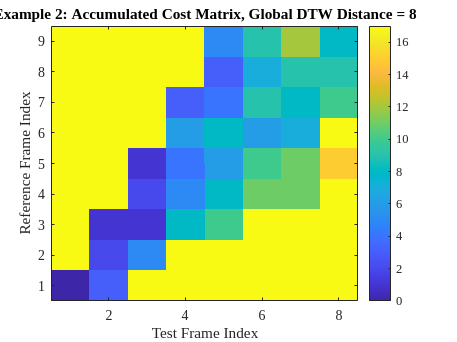


%% Example 2
% Test and reference sequences for Example 2
testSeq2 = [1; 4; 5; 2; 3; 7; 6; 1];  % 8 frames
refSeq2  = [1; 2; 5; 6; 5; 7; 4; 3; 1]; % 9 frames

% Compute DTW
[globalDistance2, A2, B2] = ComputeDTW(testSeq2, refSeq2, 1);
A_display2 = A2(:, 3:end);
A_plot2 = A_display2';

figure;
imagesc(A_plot2);
colorbar;
title(['Example 2: Accumulated Cost Matrix, Global DTW Distance = ' num2str(globalDistance2)]);
xlabel('Test Frame Index');
ylabel('Reference Frame Index');
axis xy;

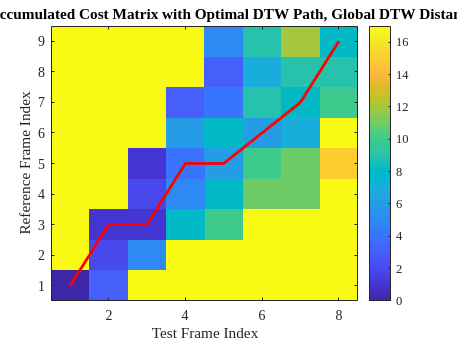


% Backtracking for Example 2
I2 = length(testSeq2);
J2 = length(refSeq2);
i = I2;
j = J2 + 2;  % Start at bottom-right of A2
path2 = [];
while i > 1 && j > 2
    path2 = [[i; j], path2];
    pointer = B2(i, j);
    switch pointer
        case 1
            j = j - 2;
        case 2
            j = j - 1;
        case 3
            % j remains unchanged
    end
    i = i - 1;
end
path2 = [[i; j], path2];
path2(2,:) = path2(2,:) - 2;
x_path2 = path2(1,:);
y_path2 = path2(2,:);

figure;
imagesc(A_plot2);
hold on;
plot(x_path2, y_path2, 'r-', 'LineWidth', 2);
colorbar;
title(['Example 2: Accumulated Cost Matrix with Optimal DTW Path, Global DTW Distance = ' num2str(globalDistance2)]);
xlabel('Test Frame Index');
ylabel('Reference Frame Index');
axis xy;


clear; clc; close all;

%% Load example data
% Adjust the file path as needed.
load("/MATLAB Drive/cv4_pzr/check/DTW-example1.mat");
% Expected variables in the MAT file:
%   ref_feat         - Reference feature matrix (J x P)
%   word_feat        - Test feature matrix (I x P)
%   dist             - Expected global DTW distance
%   acc_dist_matrix  - Expected accumulated cost matrix (size I x (J+2))
%   back_matrix      - Expected backtracking pointer matrix (size I x (J+2))
%   path             - Expected optimal DTW path (vector of length I,
%                      where each element is a reference index)

%% Compute DTW using ComputeDTW
% For 1-D sequences, we use a weight of 1.
[globalDistance_mine, A, B] = ComputeDTW(word_feat, ref_feat,1);

fprintf('Computed global DTW distance:  %f\n', globalDistance_mine);

Computed global DTW distance:  17.501665


fprintf('Expected global DTW distance:  %f\n', dist);

Expected global DTW distance:  18.630935


fprintf('Difference:                    %f\n', abs(globalDistance_mine - dist));

Difference:                    1.129270


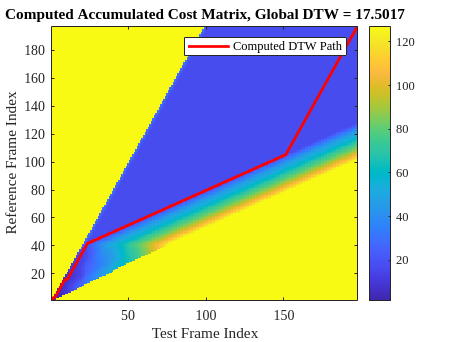


%% Prepare dimensions and remove offset for visualization
I_val = size(word_feat, 1);  % number of test frames
J_val = size(ref_feat, 1);   % number of reference frames

% For the computed cost matrix, remove the first two columns (offset)
A_display = A(:, 3:end);  % now size is [I_val x J_val]
% Transpose so that:
%   x-axis = test frames (columns)
%   y-axis = reference frames (rows)
A_plot = A_display';

%% Visualize Computed DTW Path
figure;
imagesc(A_plot);
colorbar;
title(['Computed Accumulated Cost Matrix, Global DTW = ' num2str(globalDistance_mine)]);
xlabel('Test Frame Index');
ylabel('Reference Frame Index');
axis xy;
hold on;

% Backtracking for computed DTW path:
i = I_val;
j = J_val + 2;  % starting at (I_val, J_val+2) in A
computed_path = [];
while (i > 1 && j > 2 && j <= size(B,2))
    computed_path = [[i; j], computed_path];
    pointer = B(i, j);
    switch pointer
        case 1
            if (j - 2) < 3, break; end
            j = j - 2;
        case 2
            if (j - 1) < 3, break; end
            j = j - 1;
        case 3
            % horizontal move: j remains unchanged
    end
    i = i - 1;
end
computed_path = [[i; j], computed_path];
% Adjust the reference index by subtracting the offset (2)
computed_path(2,:) = computed_path(2,:) - 2;
x_computed = computed_path(1,:);
y_computed = computed_path(2,:);
plot(x_computed, y_computed, 'r-', 'LineWidth', 2);
legend('Computed DTW Path');

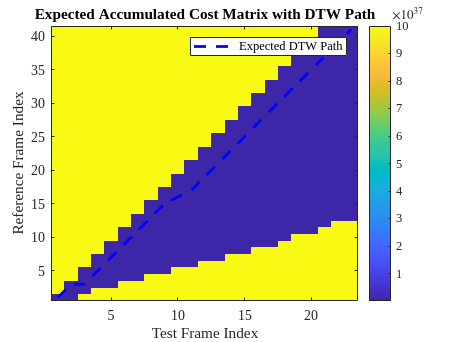


%% Visualize Expected DTW Path in a Separate Figure
% For the expected cost matrix, remove the offset from the expected accumulated cost matrix:
A_expected = acc_dist_matrix(:, 3:end);  % size becomes [I_val x J_val]
A_expected_plot = A_expected';           % transpose for visualization

figure;
imagesc(A_expected_plot);
colorbar;
title('Expected Accumulated Cost Matrix with DTW Path');
xlabel('Test Frame Index');
ylabel('Reference Frame Index');
axis xy;
hold on;

% The expected DTW path is stored in the variable "path", which is a vector
% of length I_val. Each element represents the reference index for that test frame.
x_expected = 1:length(path);
y_expected = path;  % these are the reference indices already

plot(x_expected, y_expected, 'b--', 'LineWidth', 2);
legend('Expected DTW Path');